# Seminar 2 - Multivariate Gaussian, MS, LMS, ML

**Authors:** prof. Ing. Vladimír Havlena, CSc., Ing. David Vošahlík

### Multivariate gaussian - recapitulation

In this section the multivariate normal distribution will be further studied (continuation from last seminar). Your first task here will be to:

- create a set of samples from given multivariable distribution

- compare it's sample mean and variance with the assigned ones 

- plot histogram and the pdf function for comparison.

- change the matrix P and number of samples

%% OFD: Seminar Week 2
% MATLAB excercises
% 
% Jaroslav Tabacek, 2017

%% Generate random sample from multivariate normal distribution

% Covariance matrix
P=[2 1; 1 1]*0.001;

% Mean values
C = [1 1]' ; 

% Number of random samples 
N = 1000;

samplesN01 = randn(size(P,1),N);
% Generate random samples 
samples = (C*ones(1,N) + chol(P)'*samplesN01); % chol(P)'*chol(P) = P
samples2 = (C*ones(1,N) + chol(P,'lower')*samplesN01);
% samples = mvnrnd(C,P,N);

samples = samples';
% Check covariance of the sample set
P_calc = cov(samples)

P_calc =     0.0021    0.0010
    0.0010    0.0010


C_calc = mean(samples)

C_calc =     0.9979    0.9987


norm(cov(samples) - P)

ans = 1.5120e-04

norm(mean(samples) - C)

ans = 0.0035

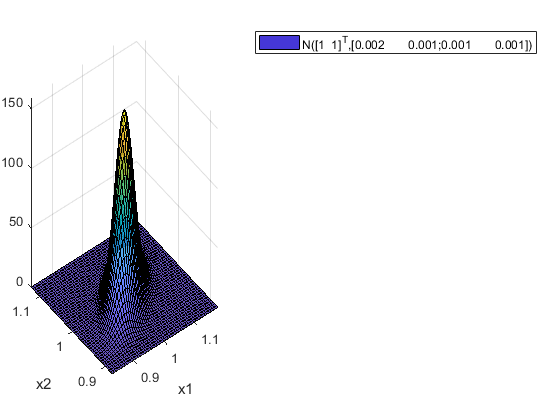


%% Multivariate gaussian

figure;
gauss2([], C, P,'FaceAlpha',0.8);

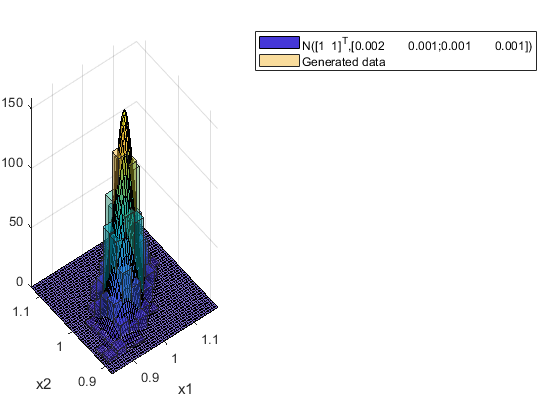


%% Multivariate gaussian with generated data

figure;
gauss2([], C, P,'FaceAlpha',0.7);
hold on 
histogram2(samples(:,1)',samples(:,2)','Normalization','pdf',...
    'DisplayName','Generated data','FaceAlpha',0.5,'FaceColor','flat')

#### Two variable normal distribution cut

The two variable normal distribution pdf function cut is 2-D and as such can be plotted. Your task will be to:

-  plot the ellipsoids of pdf cuts for given quantile value $q$ (see lecture slides for further theory).

Hints:

- $\alpha ~\textrm{inv}\chi_n^2 \left(q\right)$- see lecture slides regarding covariance elipsoids

- Using svd decomposition of covariance matrix the unit eigenvectors can be obtained ($U$ matrix)

-  If $X$ is $\textrm{NxN}$ real symmetric matrix with non-negative eigenvalues (which is special case), then eigenvalues and singular values coincide.

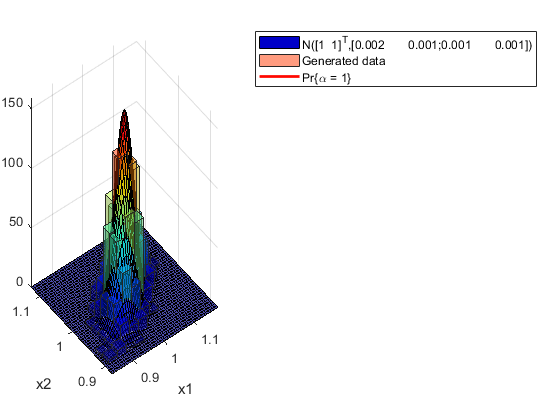

%% Plot two-dimensional normal distribution cut

% Unit circle parametrization
Ncircle = 100; % number of elements in graph
theta = [0:1/Ncircle:2*pi+1/Ncircle];

% Quantiles
quantiles = [0.25,0.5,0.75,0.9];
quant_norm = (quantiles-min(quantiles)*0.6)/0.75; % normalization used only for plotting

cm = colormap('jet');
ncm = size(cm,1);


% x,y coordinates
unit_circle(1,:) = cos(theta); % x
unit_circle(2,:) = sin(theta); % y 

% Coordinate transform 
%----------------------------------------
[U,D,V] = svd(P); % D - diagonal with squares of semi-axes length
                  %     sigma = abs(eig(A));[eig(A)>0] = eig(A) - holds for
                  %     symmetric matrices because S = UDU', U^-1=U' is
                  %     also an eigen decomposition.
                  %
                  % U = V^-1 = V' - right eigenvectors forming orthonormal
                  %     basis, i.e. directions of semi-axes

% rotation, scaling
sig_contour = U*sqrt(D)*unit_circle;
% sig_contour = chol(P,'lower')*unit_circle;

% translation
sig_contour(1,:) = sig_contour(1,:)+ C(1);
sig_contour(2,:) = sig_contour(2,:)+ C(2);
q = quantiles(1);
 
plot(sig_contour(1,:),sig_contour(2,:),...
        'LineWidth',2,'Color',cm(max(round((1-quant_norm(1))*ncm),1),:),...
        'DisplayName',['Pr\{\alpha = 1\}']);

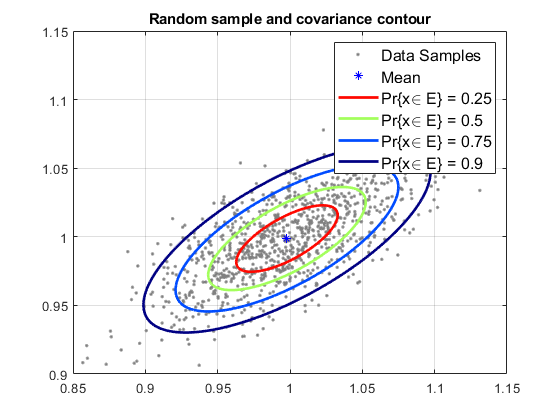




% Ellipse of the calculated covariance
[U_calc,D_calc,~] = svd(P_calc);

% Plot
figure;
% plot samples
l(1) = plot(samples(:,1),samples(:,2),'.','Color',0.5*[1 1 1],'DisplayName','Data Samples');
hold on
% plot real covariance and center
% l(2) = plot(sig_contour(1,:),sig_contour(2,:),'r');
% plot(C(1),C(2),'r*');
plot(C_calc(1),C_calc(2),'b*','DisplayName','Mean');


for i = 1:numel(quantiles)
    q = quantiles(i);
    alpha = chi2inv(q,2);
    % plot calculated covariance and center
    sig_contour_calc = U_calc*sqrt(alpha*D_calc)*unit_circle; 
    sig_contour_calc(1,:) = sig_contour_calc(1,:)+ C_calc(1);
    sig_contour_calc(2,:) = sig_contour_calc(2,:)+ C_calc(2);
    l(3+i-1) = plot(sig_contour_calc(1,:),sig_contour_calc(2,:),...
        'LineWidth',2,'Color',cm(max(round((1-quant_norm(i))*ncm),1),:),...
        'DisplayName',['Pr\{x\in E\} = ',num2str(q)]);
end
leg = legend('show');
leg.FontSize = 12;
title('Random sample and covariance contour');
grid on

 **What does this cut represent?** confidence region.

### **Mean square and linear mean square estimates**

In this section the mean square estimate will be introduced and studied. It minizes the optimality criterion $J_{\textrm{MS}}$, which is  integrated squared error


$$J_{\textrm{MS}} =\int \int {\left(x-{\hat{x} }_{\textrm{MS}} \left(y\right)\right)}^T \left(x-{\hat{x} }_{\textrm{MS}} \left(y\right)\right)p\left(x,y\right)\textrm{dx}\;\textrm{dy}\ldotp$$
 

In the following example the linear measurement model will be considered

$x=A\;y+b$,

where$A$ and $b$ are the model parameters. Your task will be: 

-  for the given mean and variance generate the samples and

- estimate the ${\hat{x} }_{\textrm{MS}}$using linear mean square algorithm (see lecture slides). 

- Try to play with different inputs of the algorithm (e.g.  number of samples, various means and variances)

n_samples =10000;        % number of samples
mu_y = 5;                                       % mean of measured points y
A_real = 3;                                     % true value of the estimated gain parameter         
b_real = 5;                                     % true value of the estimated offset parameter
sigma_y = 10;                                   % standard deviation of y
sigma_x = 10;                                   % standard deviation of x


data_y = mu_y + sigma_y.*randn([1, n_samples]);
data_x = A_real.*data_y + b_real;               % try to add another noise term:  + sigma_x.*randn([1, n_samples])

P = cov([data_y', data_x']);


A_hat = P(2,1)/P(1,1);
b_hat = mean(data_x) - A_hat*mean(data_y);

display(['Error of gain A estimate is ' num2str(abs(A_real - A_hat))]);

Error of gain A estimate is 8.8818e-16


display(['Error of offset b estimate is ' num2str(abs(b_real - b_hat))]);

Error of offset b estimate is 1.4211e-14


Look into the *\ *operator help. **How does it coincide with the linear mean square estimate?**

### **Maximum Likelihood**

This section shows two examples of Maximum Likelihood (ML) estimate. This estimation method finds the most likely function parameters to explain a set of observed data.

In many real life examples, you don't have a model, everything you get are only data. Then you have to fit data to a model. This is the right moment to use ML estimate. It chooses the model parameters (based on the values), which maximize the Likelihood function


$$\begin{array}{l}
l\left(x|y\right)=p\left(y|x\right)=\prod_{i=1}^n f\left(y|x_i \right),\\
{\hat{x} }_{\textrm{ML}} \left(y\right)=\arg \;\underset{x}{\max \;} l\left(x|y\right)\ldotp 
\end{array}$$


Then likelihood of a sample is the probability of getting that sample for an arbitrary probability distribution model.

Since it is easier to calculate sum than product, the log likelihood function is often used (log function is monotonic $\longrightarrow$ if there exists value $x$ that maximizes likelihood function, then that same value $x$ also maximizes the log likelihood function). The likelihood equation is then 

$\frac{\partial \;\ln \;l\left(x|y\right)}{\textrm{∂}\;\textrm{x}}|_{x={\hat{x} }_{\textrm{ML}} } =0$.

#### Maximum Likelihood Estimate for Linear Parameter with Varying Noise

In the first example, we consider linear model 


$$y=\textrm{Cx}+e$$


with unknown parameter $x$, which we want to estimate using ML, and noise $e$.

Your first task is to:

- estimate mean and variance using maximum likelihood and

- compare it to sample mean and variance.

n = 20;                                     % number of measuremenets. Put your own value.
C = ones(n,1);
x = 2;                                      % parameter value    
rr = 0.01+9*rand(n,1).^2;                   % noise variance
R = diag(rr);
sige = sqrt(rr);
Y = C*x + diag(sige)*randn(n,1);            % <-- data with variable noise variance
% ML estimate
X_ml = (C'/R*C)\C'/R*Y;                     % <-- ML mean
sig2_ml = inv(C'/R*C);                      % <-- ML variance
% SM estimate 
X_smp = sum(Y)/n;                           % <-- SM mean
sig2_smp = (Y-X_smp)'*(Y-X_smp)/(n-1);      % <-- SM variance

Next step is visualization of the data. We show the data distribution, $x_{\textrm{true}}$, ${\hat{x} }_{\textrm{ML}}$ and also ${\hat{x} }_{\textrm{SM}}$.

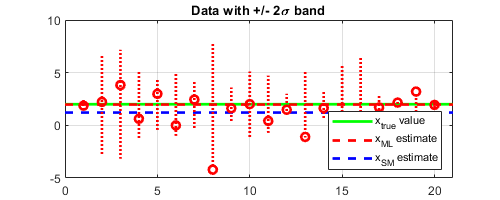

% Plot
f1 = figure;
p1 = plot([0,n+1],[x x],'g','LineWidth',2);
xlim([0,n+1])
hold on
p2 = plot([0,n+1],[X_ml,X_ml],'r--','LineWidth',2);
p3 = plot([0,n+1],[X_smp,X_smp],'b--','LineWidth',2);
for i=1:n
    plot([i,i],[x-2*sige(i),x+2*sige(i)],'r:','LineWidth',2);
    plot(i,Y(i),'ro','LineWidth',2);
end
grid on
set(f1,'Position',[440 378 500 200])
title('Data with +/- 2\sigma band')
hold off
legend([p1 p2 p3],{'x_{true} value','x_{ML} estimate','x_{SM} estimate'},'Location','southeast')

Adding also a result where the comparison of variances is more meaningfull. These can differ and this is caused by the maximum likelihood method "trusting" (it has small variance) in it's estimate. It is due to the fact that the sample variance is variance of the random variable, but the maximum likelihood variance is variance of the estimate.

n = 200;                                     % number of measuremenets. Put your own value.
C = ones(n,1);
x = 2;                                      % parameter value    
R = 9;                                      % noise variance

sige = sqrt(R);
Y = C*x + diag(sige)*randn(n,1);            % <-- data with variable noise variance
% ML estimate
X_ml = (C'/R*C)\C'/R*Y;                     % <-- ML mean
sig2_ml = inv(C'/R*C);                      % <-- ML variance
% SM estimate 
X_smp = sum(Y)/n;                           % <-- SM mean
sig2_smp = (Y-X_smp)'*(Y-X_smp)/(n-1);      % <-- SM variance

 ML is for the linear measurement model unbiased, efficient and consistent estimate (see lecture slides). 

**How is ML different to the mean square estimate?**

Now we investigate the log likelihood function. Your task will be to:

- compute the log likelihood function for the problem above.

The plots are already prepared for you.

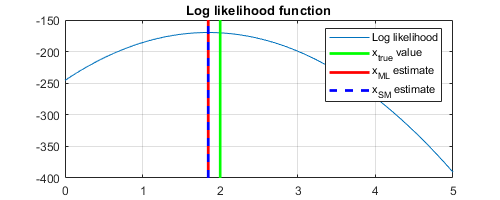

% Likelihood function
XX = (0:0.025:5)';
LY = XX;
[m,~] = size(XX);
for i=1:m
   LY(i) = -(Y-C*XX(i))'/R*(Y-C*XX(i));     % <-- log likelihood function
end

% Plot
f2 = figure;
plot(XX,LY)
grid on
hold on
yl =ylim();
plot([x,x],yl,'g','LineWidth',2);
plot([X_ml,X_ml],yl,'r-','LineWidth',2);
plot([X_smp,X_smp],yl,'b--','LineWidth',2);
hold off
set(f2,'Position',[440 378 500 200])
title('Log likelihood function')
legend('Log likelihood','x_{true} value','x_{ML} estimate','x_{SM} estimate')

As the last step, we evaluate probability distribution nearby the calculated mean and compare it to the true value. Here your task will be to:

- calculate the values of corresponding probability density functions for the above determined ML and SM mean and variance.

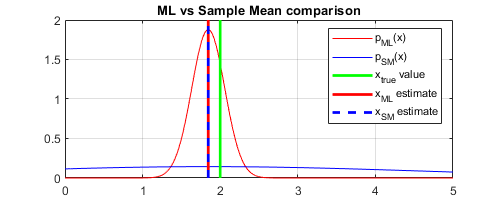

% evaluate distibution at XX points
px_ml = 1/sqrt(2*pi*sig2_ml)*exp(-(XX-X_ml).^2/(2*sig2_ml));        % <-- probability distribution p_ml(x)
px_smp = 1/sqrt(2*pi*sig2_smp)*exp(-(XX-X_smp).^2/(2*sig2_smp));    % <-- probability distribution p_sm(x)

% Plot
f3 = figure;
plot(XX, px_ml,'r')
hold on
plot(XX, px_smp,'b')
grid on
yl =ylim();
plot([x,x],yl,'g','LineWidth',2);
plot([X_ml,X_ml],yl,'r-','LineWidth',2);
plot([X_smp,X_smp],yl,'b--','LineWidth',2);
hold off
set(f3,'Position',[440 378 500 200])
title('ML vs Sample Mean comparison')
legend('p_{ML}(x)','p_{SM}(x)','x_{true} value','x_{ML} estimate','x_{SM} estimate')

Additionaly, you can try to **increase number of samples** (data size) and observe how the parameter estimations behaves.

#### Maximum Likelihood Estimate for Bernoulli Distribution

Next example is the estimation of parameter of coin tossing. Let's have coin tossing experiment with following result:

$P\left\lbrace X=1\right\rbrace =\theta ,\;P\left\lbrace X=0\right\rbrace =1-\theta \;\longrightarrow p\left(x|\theta \right)=\theta^x {\left(1-\theta \right)}^{1-x} ,x\in \left\lbrace 0,1\right\rbrace$.

For n independent trials: 

$p_n \left(x|\theta \right)=\prod_{i=1}^n \theta^{x_i } {\left(1-\theta \right)}^{1-x_i }$.

Then your task is to calculate log likelihood function, find the derivative (max) and determine ${\hat{\theta} }_{\textrm{ML}}$ (see lecture slides).

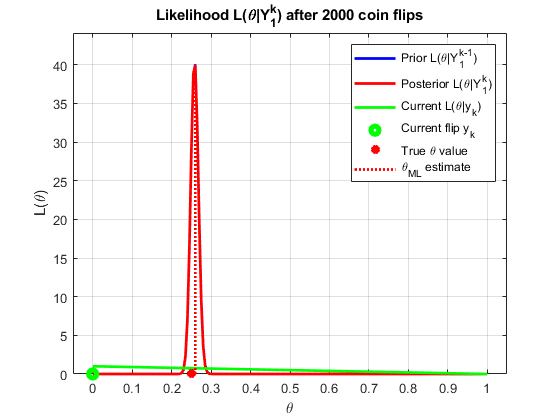

Theta = 0.25;
N = 2000;                               % number of flips
n = 201;                                % number of plot points
p_theta_prior = ones(1,n);              % <-- prior distribution of theta
theta_axis = (0:n-1)/(n-1);             
plot_set = [1:10,100:100:2000];         % iteration steps to be plotted
% start flipping the coin
figure;
for f = 1:N
    if rand()<Theta
        x = 1; 
        L = theta_axis;                 % <-- likelihood function for X=1 (head)
    else
        x = 0;
        L = 1 - theta_axis;             % <-- likelihood function for X=0 (tail)
    end
    p_theta_posterior = L .* p_theta_prior;
    p_theta_posterior = p_theta_posterior / sum(p_theta_posterior)*(n-1);
    p_max = max([p_theta_posterior, p_theta_prior]);
    p_scale = ceil(10*1.1*p_max)/10;
    % find max likelihood value and its index
    p_max = max(p_theta_posterior);
    ip_max = max((p_theta_posterior == p_max) .* theta_axis);
    
    % Plot
    if ismember(f,plot_set)    
        plot(theta_axis, p_theta_prior,'b','linewidth',2);
        hold on    
        plot(theta_axis, p_theta_posterior,'r','linewidth',2);
        plot(theta_axis, L,'g','linewidth',2);
        plot(x, 0, 'go','linewidth',4)
        plot(Theta,0,'r*','linewidth',4)
        plot([ip_max, ip_max],[0, p_max],'r:','linewidth',2)
        legend(' Prior L(\theta|Y_1^{k-1})',' Posterior L(\theta|Y_1^k)',' Current L(\theta|y_k)',' Current flip y_k',' True \theta value',' \theta_{ML} estimate')
        axis([-0.05, 1.05, 0.00, p_scale])
        grid on
        xlabel('\theta');
        ylabel('L(\theta)');
        title(['Likelihood L(\theta|Y_1^k) after ',int2str(f),' coin flips'])
        hold off
        grid on
        pause(1.5);
    end
    p_theta_prior = p_theta_posterior;     % <-- new prior distribution of theta
end

### Appendix

Here are some handy functions that can be used for your purposes.

function varargout = gauss2(x, mi, P, varargin)
%GAUSS2 Bivariate gaussian bell-function.
% P = GAUSS2(x,mi,P) calculate probability P of value(s) x in a normal
% distribution defined by mean value mi and variance P
%
% GAUSS2(x,mi,P,...) plot gaussian bell-function defined by mean mi and
% covariance P and plot a marker at position(s) x (put '[]' for none). Plot options can be
% specified. Example: gauss(...,'Linewidth',2,'Color','b');

% Matisko 2010, Dostal 2013, Tabacek 2017

if nargout == 1
    
    [x1,x2] = meshgrid(x(1,:),x(2,:));
    x_l = [reshape(x1,1,numel(x1)); reshape(x2,1,numel(x2))];
    % calc probability of point(s) x
    z = (sqrt((2*pi)^2*det(P)))^(-1) .* exp( -diag( (x_l - mi)' / P * (x_l - mi) ) / 2 );
    varargout{1} = reshape(z,size(x1));
    
elseif nargout == 0
    % plot gaussian
    
    % number of points in graph
    M = 50;
    minm = (mi-4*sqrt(diag(P)));
    maxm = (mi+4*sqrt(diag(P)));
    step = (maxm - minm)/M;
    s = [minm(1)+step(1):step(1):maxm(1);
        minm(2)+step(2):step(2):maxm(2)];
    [s1,s2] = meshgrid(s(1,:),s(2,:));
    gs = gauss2(s,mi,P);
    
    if ~isempty(x)
        gx = gauss2(x,mi,P);
        [x1,x2] = meshgrid(x(1,:),x(2,:));
    else
        x1 = [];
        x2 = [];
        gx = [];
    end
    
    ishld = ishold;
    %plot
    if nargin == 3
        
        surf(s1,s2,gs,'DisplayName',['N([',num2str(mi'),']^{T},[',num2str(P(1,:)),';',num2str(P(2,:)),'])']);
        hold on
        plot3(reshape(x1,numel(x1),1),reshape(x2,numel(x2),1),reshape(gx,numel(gx),1),'r');
        
        if ~ishld
            hold off
        end
        
    elseif nargin > 3
        
        surf(s1,s2,gs,varargin{:},'DisplayName',['N([',num2str(mi'),']^{T},[',num2str(P(1,:)),';',num2str(P(2,:)),'])']);
        hold on
        plot3(reshape(x1,numel(x1),1),reshape(x2,numel(x2),1),reshape(gx,numel(gx),1),'r');
        if ~ishld
            hold off
        end
        
    else
        error('Wrong number of input parameters. See ''help gauss''');
    end
    legend show
    xlim([min(s(1,:)),max(s(1,:))]);
    ylim([min(s(2,:)),max(s(2,:))]);
    xlabel('x1');
    ylabel('x2');
else
    error('Wrong number of output parameters. See ''help gauss''');
end
end
